%% comparar_ensayos.m
% Overlay of several trials (VP_<code>_robots.csv exported by VidFetch): V_mean(t), <|omega|>(t),
% kinetic energy, histogram, PDF and 1 - F(v), one window per plot, plus a summary table.
%
% - Files: list them in `archivos` or leave it empty to pick them in a dialog (multi-select).
% - Split recordings: if you pick VP_<code>(1)_robots.csv and VP_<code>(2)_robots.csv they are joined
%   into one trial using the gap stored in datos/video/cortes.json.
% - Time plots show only the moving average (raw series of several trials overlap too much).
% - Distributions use the raw data (unsmoothed) so that widths and tails are comparable; the
%   histogram is normalised as a fraction because trials have different durations.

clear; clc;

%% ===================== Parameters =====================
carpeta  = "C:\Users\dylan\Desktop\Proyecto_PresionRecintoCircular\datos\video\trayectorias";
archivos = strings(0);   % e.g. [fullfile(carpeta,"VP_20263010_1200_22R_60_robots.csv"), ...]; empty -> dialog

suav_s         = 15;     % moving average of the time plots [s]
usar_media     = true;   % distributions of: true = V_mean per frame, false = individual |v|
dist_suavizada = false;  % true: distributions of the smoothed V_mean (changes width and tails!)
n_clases       = 55;     % histogram / PDF bins (common to all trials)

umbral   = NaN;         % jam threshold on the smoothed V_mean [mm/s] (same default as velocidades.py)
suav_atasco_s = 15;      % moving median for the jam criterion [s]
min_atasco_s  = 10;      % minimum jam duration [s]

m_g  = NaN;              % robot mass [g]; NaN -> energy per unit mass
k_I  = 0.5;              % I = k_I * m * R^2 (0.5 = uniform disk; assumption)
R_mm = 33/2;             % robot radius [mm]

guardar_figuras = false; % true: export every figure as vector PDF
carpeta_figuras = "C:\Users\dylan\Desktop\Proyecto_PresionRecintoCircular\informes\comparacion_matlab";

%% ===================== Choose files =====================
if isempty(archivos)
    [nom, ruta] = uigetfile(fullfile(carpeta, "*_robots.csv"), ...
                            "Elegí uno o más VP_..._robots.csv", "MultiSelect", "on");
    if isequal(nom, 0)
        error("No se eligió ningún archivo.");
    end
    archivos = string(fullfile(ruta, string(nom)));
end

archivos = archivos(:);

% Group parts of split recordings by trial code
codigos = strings(size(archivos));
partes  = ones(size(archivos));
for i = 1:numel(archivos)
    [~, base] = fileparts(archivos(i));
    base = char(base);                                   % char: an unmatched group gives ''
    tok = regexp(base, '^VP_(.+?)(?:\((\d+)\))?_robots$', 'tokens', 'once');
    if isempty(tok)
        error("Nombre inesperado: %s (se espera VP_<código>_robots.csv)", base);
    end
    codigos(i) = string(tok{1});
    if numel(tok) > 1 && ~isempty(tok{2})
        partes(i) = str2double(tok{2});
    end
end
[cod_unicos, ~, idx_cod] = unique(codigos, "stable");

%% ===================== Load and process every trial =====================
if isnan(m_g)
    escala = 1;    unidad_E = 'E / m [\muJ/kg]';
else
    escala = m_g;  unidad_E = 'E [nJ]';            % 1 g * 1 uJ/kg = 1 nJ
end
avg = @(x) mean(x, 'omitnan');
D = struct([]);

for c = 1:numel(cod_unicos)
    sel = find(idx_cod == c);
    [~, orden] = sort(partes(sel));
    sel = sel(orden);
    T = table();
    t_fin = NaN;  frame_fin = -1;
    for j = 1:numel(sel)
        f = archivos(sel(j));
        fprintf("Leyendo %s ...\n", f);
        opts = detectImportOptions(f);
        opts.SelectedVariableNames = intersect({'frame','t_s','particle','speed_mm_s','omega_rad_s'}, ...
                                               opts.VariableNames, 'stable');
        Tj = readtable(f, opts);
        if j > 1                                         % next part of a split recording
            hueco = hueco_corte(f, cod_unicos(c), j - 1);
            Tj.t_s   = Tj.t_s + t_fin + hueco;           % same rule as comparar_modos.py
            Tj.frame = Tj.frame + frame_fin + 1 + round(hueco * 3);
            fprintf("  parte %d unida con un hueco de %.2f s\n", partes(sel(j)), hueco);
        end
        t_fin = max(Tj.t_s);  frame_fin = max(Tj.frame);
        if isempty(T), T = Tj; else, T = [T; Tj]; end %#ok<AGROW>
    end

    N = numel(unique(T.particle));
    [g, ~] = findgroups(T.frame);
    t  = splitapply(avg, T.t_s, g);                      % video time [s]
    v  = splitapply(avg, T.speed_mm_s, g);               % V_mean [mm/s]
    e_tr = N * splitapply(avg, 0.5 * T.speed_mm_s.^2, g);
    if ismember('omega_rad_s', T.Properties.VariableNames)
        w     = rad2deg(splitapply(avg, abs(T.omega_rad_s), g));                  % <|omega|> [deg/s]
        e_rot = N * splitapply(avg, 0.5 * k_I * R_mm^2 * T.omega_rad_s.^2, g);
    else
        w = nan(size(t));  e_rot = nan(size(t));
    end
    [t, orden] = sort(t);
    v = v(orden);  w = w(orden);  e_tr = escala * e_tr(orden);  e_rot = escala * e_rot(orden);

    mm = @(x) movmean(x, suav_s, 'omitnan', 'SamplePoints', t);
    if usar_media
        muestras = v;
        if dist_suavizada, muestras = mm(v); end
    else
        muestras = T.speed_mm_s;
    end
    muestras = muestras(isfinite(muestras));

    [frac, n_at, dmax] = atascos(t, v, umbral, suav_atasco_s, min_atasco_s);

    D(c).codigo   = cod_unicos(c);
    D(c).etiqueta = etiqueta(cod_unicos(c));
    D(c).N        = N;
    D(c).t        = t;
    D(c).v_s      = mm(v);
    D(c).w_s      = mm(w);
    D(c).Etr_s    = mm(e_tr);
    D(c).Erot_s   = mm(e_rot);
    D(c).Etot_s   = mm(e_tr + e_rot);
    D(c).muestras = muestras;
    D(c).resumen  = [mean(v,'omitnan'), std(v,'omitnan'), median(muestras), mean(w,'omitnan'), ...
                     mean(e_tr,'omitnan'), mean(e_rot,'omitnan'), ...
                     mean(e_rot,'omitnan') / mean(e_tr,'omitnan'), 100 * frac, n_at, dmax];
end

Leyendo C:\Users\dylan\Desktop\Proyecto_PresionRecintoCircular\datos\video\trayectorias\VP_20263010_1100_22QL_60_robots.csv ...
Leyendo C:\Users\dylan\Desktop\Proyecto_PresionRecintoCircular\datos\video\trayectorias\VP_20263010_1200_22R_60_robots.csv ...
Leyendo C:\Users\dylan\Desktop\Proyecto_PresionRecintoCircular\datos\video\trayectorias\VP_20263010_1430_22R_60_robots.csv ...
Leyendo C:\Users\dylan\Desktop\Proyecto_PresionRecintoCircular\datos\video\trayectorias\VP_20263010_1600_22QL_60(1)_robots.csv ...
Leyendo C:\Users\dylan\Desktop\Proyecto_PresionRecintoCircular\datos\video\trayectorias\VP_20263010_1600_22QL_60(2)_robots.csv ...


  parte 1 unida con un hueco de 31.79 s



%% ===================== Summary table =====================
nombres = {'V_media_mm_s','V_desvio_temporal','mediana_dist_mm_s','omega_abs_deg_s', ...
           'E_tras','E_rot','E_rot_sobre_E_tras','atasco_pct','n_atascos','atasco_max_s'};
R = array2table(vertcat(D.resumen), 'VariableNames', nombres, 'RowNames', cellstr([D.etiqueta]));
fprintf("\nResumen (energía en %s, umbral %.2f mm/s sobre V_media con mediana móvil %g s, >= %g s)\n", ...
        strrep(unidad_E, '\mu', 'u'), umbral, suav_atasco_s, min_atasco_s);


Resumen (energía en E / m [uJ/kg], umbral NaN mm/s sobre V_media con mediana móvil 15 s, >= 10 s)


disp(R);

                          V_media_mm_s    V_desvio_temporal    mediana_dist_mm_s    omega_abs_deg_s    E_tras    E_rot     E_rot_sobre_E_tras    atasco_pct    n_atascos    atasco_max_s
                          ____________    _________________    _________________    _______________    ______    ______    __________________    __________    _________    ____________

    30/10 11:00 · 22QL       1.0645            0.51199                1.033             8.1845          26.93    70.216          2.6074              0             0             0      
    30/10 12:00 · 22R       0.92814             0.3904              0.

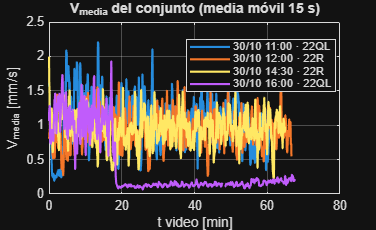


%% ===================== Common distribution bins =====================
if usar_media
    txt_dist = 'V_{media} por cuadro';
    if dist_suavizada, txt_dist = sprintf('V_{media} suavizada %g s (cambia ancho y colas)', suav_s); end
else
    txt_dist = '|v| individual';
end
v_max   = max(cellfun(@max, {D.muestras}));
edges   = linspace(0, v_max, n_clases + 1);
centros = 0.5 * (edges(1:end-1) + edges(2:end));

%% ===================== Figures: one window per plot =====================
C = lines(numel(D));
txt_mm = sprintf('media móvil %g s', suav_s);
leg = cellstr([D.etiqueta]);
figs = gobjects(0);

% --- 1. V_mean vs time ------------------------------------------------------------
figs(end+1) = nueva_fig('V media vs tiempo');
for c = 1:numel(D)
    [x, y] = romper_huecos(D(c).t, D(c).v_s);
    plot(x/60, y, 'LineWidth', 1.6, 'Color', C(c,:)); hold on;
end
yline(umbral, '--', sprintf('umbral %.2f mm/s', umbral), 'HandleVisibility', 'off');
hold off; grid on;
title(['V_{media} del conjunto (' txt_mm ')']);
xlabel('t video [min]'); ylabel('V_{media} [mm/s]'); legend(leg, 'Location', 'best');

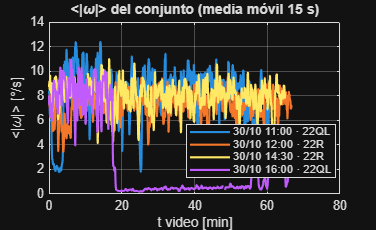


% --- 2. <|omega|> vs time ---------------------------------------------------------
figs(end+1) = nueva_fig('Rotacion media vs tiempo');
for c = 1:numel(D)
    [x, y] = romper_huecos(D(c).t, D(c).w_s);
    plot(x/60, y, 'LineWidth', 1.6, 'Color', C(c,:)); hold on;
end
hold off; grid on;
title(['<|\omega|> del conjunto (' txt_mm ')']);
xlabel('t video [min]'); ylabel('<|\omega|> [°/s]'); legend(leg, 'Location', 'best');

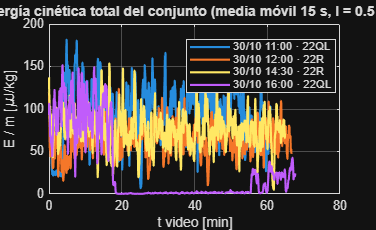


% --- 3. Total kinetic energy --------------------------------------------------------
figs(end+1) = nueva_fig('Energia cinetica total');
for c = 1:numel(D)
    [x, y] = romper_huecos(D(c).t, D(c).Etot_s);
    plot(x/60, y, 'LineWidth', 1.6, 'Color', C(c,:)); hold on;
end
hold off; grid on;
title(sprintf('Energía cinética total del conjunto (%s, I = %.2g mR^2)', txt_mm, k_I));
xlabel('t video [min]'); ylabel(unidad_E); legend(leg, 'Location', 'best');

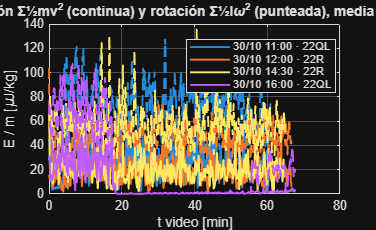


% --- 4. Translation (solid) and rotation (dashed) -----------------------------------
figs(end+1) = nueva_fig('Energia traslacion y rotacion');
h = gobjects(numel(D), 1);
for c = 1:numel(D)
    [x, y] = romper_huecos(D(c).t, D(c).Etr_s);
    h(c) = plot(x/60, y, '-', 'LineWidth', 1.4, 'Color', C(c,:)); hold on;
    [x, y] = romper_huecos(D(c).t, D(c).Erot_s);
    plot(x/60, y, '--', 'LineWidth', 1.4, 'Color', C(c,:), 'HandleVisibility', 'off');
end
hold off; grid on;
title(sprintf('Traslación \\Sigma½mv^2 (continua) y rotación \\Sigma½I\\omega^2 (punteada), %s', txt_mm));
xlabel('t video [min]'); ylabel(unidad_E); legend(h, leg, 'Location', 'best');

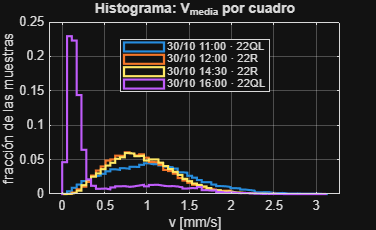


% --- 5. Histogram (fraction, so different durations are comparable) -----------------
figs(end+1) = nueva_fig('Histograma de velocidades');
for c = 1:numel(D)
    histogram(D(c).muestras, edges, 'Normalization', 'probability', 'DisplayStyle', 'stairs', ...
              'LineWidth', 1.6, 'EdgeColor', C(c,:)); hold on;
end
hold off; grid on;
title(['Histograma: ' txt_dist]);
xlabel('v [mm/s]'); ylabel('fracción de las muestras'); legend(leg, 'Location', 'best');

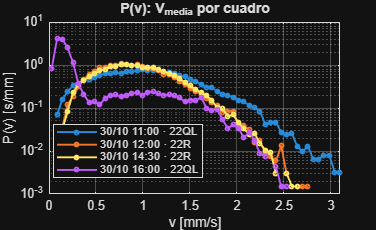


% --- 6. PDF ------------------------------------------------------------------------
figs(end+1) = nueva_fig('Densidad de probabilidad P(v)');
for c = 1:numel(D)
    p = histcounts(D(c).muestras, edges, 'Normalization', 'pdf');
    p(p == 0) = NaN;                                   % log axis: skip empty bins
    semilogy(centros, p, 'o-', 'LineWidth', 1.4, 'MarkerSize', 3, 'Color', C(c,:)); hold on;
end
hold off; grid on;
title(['P(v): ' txt_dist]);
xlabel('v [mm/s]'); ylabel('P(v) [s/mm]'); legend(leg, 'Location', 'best');

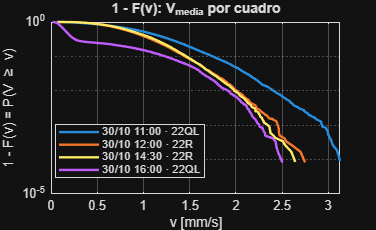


% --- 7. 1 - F(v) ---------------------------------------------------------------------
figs(end+1) = nueva_fig('1 - F(v)');

for c = 1:numel(D)
    x = sort(D(c).muestras) ;
    y = (numel(x):-1:1)' / numel(x);                   % P(V >= v), never 0
    semilogy(x, y, 'LineWidth', 1.8, 'Color', C(c,:)); hold on;
end
if usar_media && ~dist_suavizada
    xline(umbral, '--', sprintf('umbral %.2f', umbral), 'HandleVisibility', 'off');
end
hold off; grid on;
title(['1 - F(v): ' txt_dist]);
xlabel('v [mm/s]'); ylabel('1 - F(v) = P(V \geq v)'); legend(leg, 'Location', 'best');


%% ===================== Export =====================
if guardar_figuras
    if ~isfolder(carpeta_figuras), mkdir(carpeta_figuras); end
    for i = 1:numel(figs)
        nombre = matlab.lang.makeValidName(figs(i).Name);
        exportgraphics(figs(i), fullfile(carpeta_figuras, nombre + ".pdf"), 'ContentType', 'vector');
    end
    writetable(R, fullfile(carpeta_figuras, "resumen_matlab.csv"), 'WriteRowNames', true);
    fprintf("Figuras y resumen guardados en %s\n", carpeta_figuras);
end

%% ===================== Local functions =====================
function f = nueva_fig(nombre)
    f = figure('Name', nombre, 'NumberTitle', 'off', 'Position', [100 100 950 580]);
end

function txt = etiqueta(codigo)
    % '20263010_1200_22R_60' -> "30/10 12:00 · 22R" (files store AAAADDMM; August logs AAAAMMDD)
    p = split(codigo, "_");
    d = char(p(1));  hm = char(p(2));
    a = str2double(d(5:6));  b = str2double(d(7:8));
    if a <= 12 && b > 12
        dia = b;  mes = a;
    else
        dia = a;  mes = b;
    end
    txt = string(sprintf('%02d/%02d %s:%s · %s', dia, mes, hm(1:2), hm(3:4), char(p(3))));
end

function hueco = hueco_corte(archivo, codigo, k)
    % Gap [s] between part k and k+1 of a split recording, from datos/video/cortes.json
    cortes = fullfile(fileparts(fileparts(archivo)), "cortes.json");
    if ~isfile(cortes)
        error("%s está partido pero no existe %s (correr medir_corte.py).", codigo, cortes);
    end
    J = jsondecode(fileread(cortes));
    campo = matlab.lang.makeValidName(char(codigo));
    if ~isfield(J, campo)
        error("%s no figura en cortes.json.", codigo);
    end
    hueco = J.(campo).hueco_s(k);
end

function [frac, n, dmax] = atascos(t, v, umbral, suav_s, min_s)
    % Jam = moving median of V_mean below the threshold for at least min_s (as in velocidades.py)
    s = movmedian(v, suav_s, 'omitnan', 'SamplePoints', t);
    abajo = s(:) < umbral;
    d = diff([false; abajo; false]);
    ini = find(d == 1);  fin = find(d == -1) - 1;
    dt = median(diff(t));
    dur = t(fin) - t(ini) + dt;
    ok = dur >= min_s;
    mascara = false(size(abajo));
    for j = find(ok)'
        mascara(ini(j):fin(j)) = true;
    end
    frac = mean(mascara);
    n = nnz(ok);
    dmax = max([dur(ok); 0]);
end

function [x, y] = romper_huecos(t, y)
    % Insert a NaN where time jumps (gap of a split video) so the line is not drawn across it
    salto = find(diff(t) > 5 * median(diff(t)));
    x = t(:);  y = y(:);
    for j = flipud(salto(:))'
        x = [x(1:j); (x(j) + x(j+1)) / 2; x(j+1:end)];
        y = [y(1:j); NaN; y(j+1:end)];
    end
end